## Question Section

In this project, we will consider the question: when do international travel bans need to go into effect in order to reduce the peak infection by 50%?

## Model Section

### Plan

We will use an agent-based SIR model to solve this.  Our model will simulate a population that starts as Susceptible, can be Infected, and can become Recovered.  

We will have one connectivity graph where strongly connected clusters representing countries have weak connections between them (representing international travel).

Once a certain number of global infections (s) is reached, we will cut the weak connections between clusters, representing a 100% effective travel ban between countries.  We will stay in this banned state for the rest of the simulation.

Here are our graphs.

country_population = 100;
number_of_countries = 5;
domestic_connection_weight = 100;
international_connection_weight = 0.001;


total_pop = country_population * number_of_countries;



function [con_mat] = make_con_mat(country_pop, country_num, dom_weight, int_weight)
    total_pop = country_pop * country_num;

    population_pattern = dom_weight * (ones(country_pop) - eye(country_pop));

    con_mat = ones(total_pop) * int_weight;

    for i = 0:(country_num - 1)
        offset = i * country_pop;
        con_mat(offset + (1:country_pop), offset + (1:country_pop)) = population_pattern;
    end
end

con_mat_wout_bans = make_con_mat(country_population, number_of_countries, domestic_connection_weight, international_connection_weight);

con_mat_w_bans = make_con_mat(country_population, number_of_countries, domestic_connection_weight, 0);


Connectivity Graph Without Bans

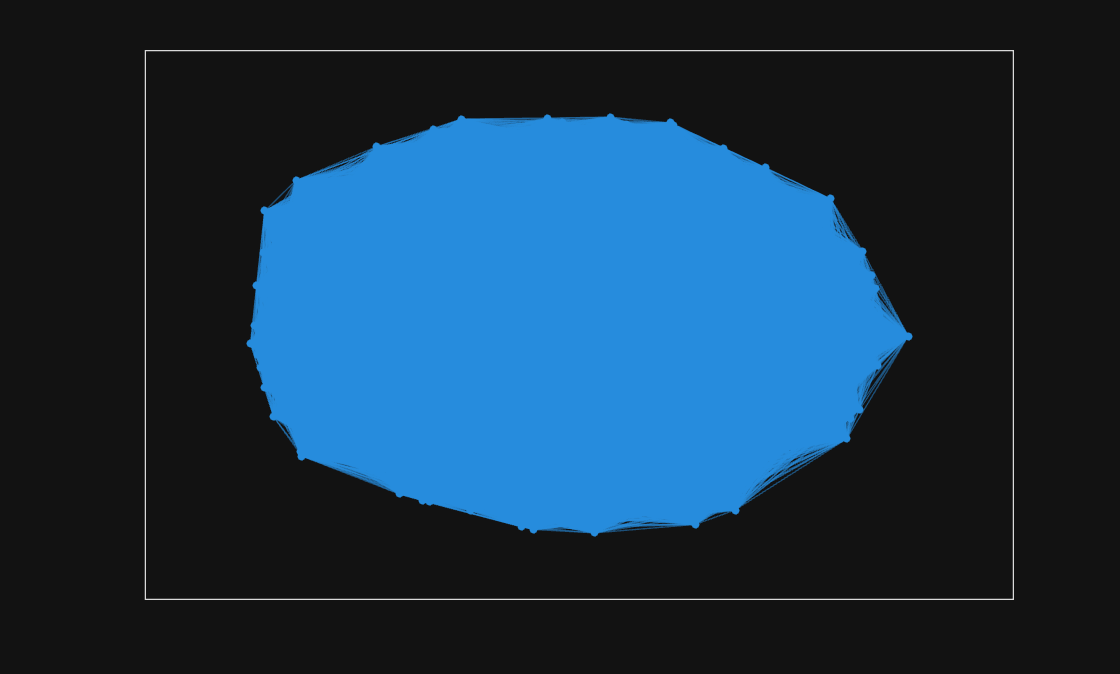

g = graph(con_mat_wout_bans);


plot(g, 'Layout', 'force');

Connectivity Graph With Bans

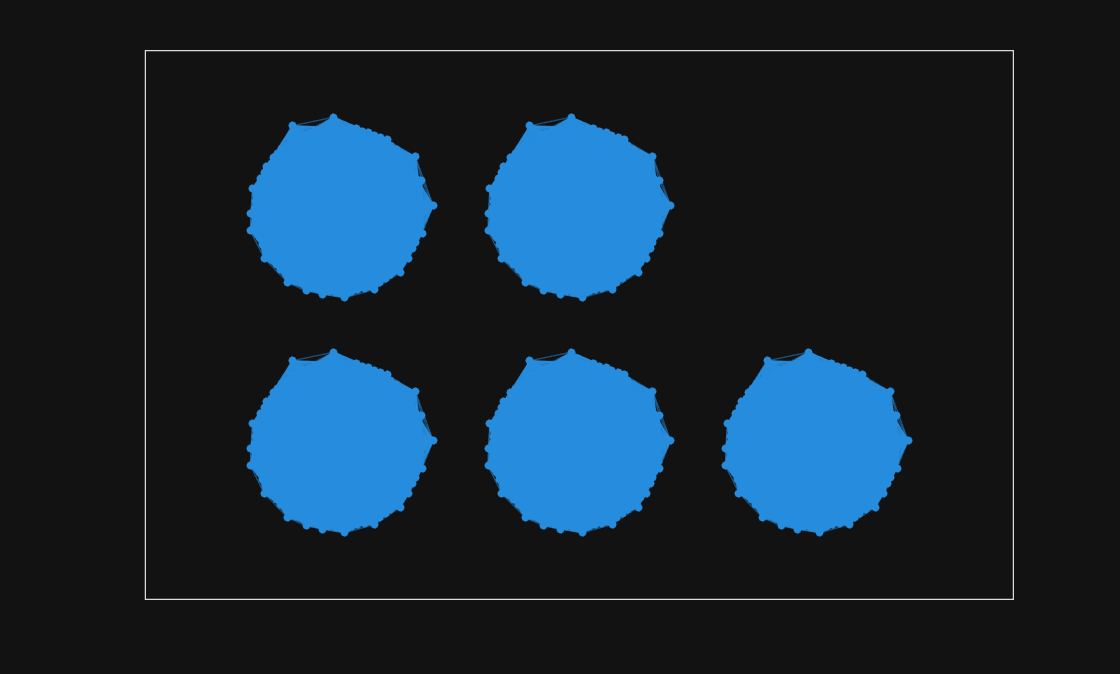

g = graph(con_mat_w_bans);


plot(g, 'Layout', 'force', 'WeightEffect', 'direct');

We will first run the simulation with no travel bans to get a control sample

We will then run the simulation with travel bans, and test different values of s with a parameter sweep, looking at infection peak as our metric

We will select the value of s that creates an infection peak 50% of the control test's infection peak

### Implementation

function [Sh, Ih, Rh] = simulate_absir_bans(M_unbanned, M_banned, Iv0, T, infection_rate, recovery_rate, ban_percent)
% Simulate agent-based transmission model. Uses a graph to represent social
% connectivity between agents.
% 
% Note: You may find it helpful to summarize the state history matrices via
% summation. For instance sum(Ih, 1) will return the total number of
% infected persons at each timestep in the simulation.
%
% Inputs
%   M_unbanned (square matrix): Adjacency matrix while bans aren't in
%   effect
%   M_banned (square matrix): Adjecency matrix while bans are in
%   Iv0 (column vector): Initial infection state
%   T (integer): Number of timesteps to simulate
%   infection_rate (float): Infection rate (probabilistic)
%   recovery_rate (float): Recovery rate (probabilistic)
%   ban_percent (float): The percent of the population that needs to be
%   infected in order for the ban to be in effect
% 
% Returns
%   Sh (matrix): Susceptible state history
%   Ih (matrix): Infected state history
%   Rh (matrix): Recovered state history

    % Setup
    dim = length(Iv0);  % Dimensions of initial state
    Ih = zeros(dim, T); % Infection history
    Ih(:, 1) = Iv0; % Record the initial state to infection history
    Rh = zeros(dim, T); % Recovery history
    
    % Construct an "action" helper function
    function [I, R] = action(I, R, M)
        % Compute infection probabilities based on the social graph
        v_eff = infection_rate * M * I;
        v_pr = v_eff ./ (1 + v_eff);
        
        % Draw random values
        v_infect = rand(dim, 1) <= v_pr;
        v_recover = rand(dim, 1) <= recovery_rate;
        
        % Infect non-recovered individuals
        I = I | v_infect & (~R);
        % Recover infected individuals
        R = R | (I & v_recover);
        I = I & (~R);
    end

    % Run simulation
    for i = 2:T
        total_infections = sum(Ih(:, i-1));
        
        
        M = M_unbanned;
        if (total_infections / length(Ih(:, 1))) > ban_percent

            M = M_banned;
        end
        disp("Infected %: " + string(total_infections / length(Ih(:, 1))));

        [Ih(:, i), Rh(:, i)] = action(M, Ih(:, i-1), Rh(:, i-1));
    end
    
    % Compute susceptible history
    Sh = ones(dim, T) - Ih - Rh;
end

Implement an SIR_agent_bans() model

initial_infections = zeros(total_pop, 1);
initial_infections(1) = 1;

[~, Ih, ~] = simulate_absir_bans(con_mat_wout_bans, con_mat_w_bans, initial_infections, 100, 0.7, 0.1, 1)

Infected %: 0.002


Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in computational_essay>simulate_absir_bans/action (line 69)
        v_eff = infection_rate 


% Summarize the total number of infected individuals over time
totalInfected = sum(Ih, 1);
figure;
plot(totalInfected);
xlabel('Time Step');
ylabel('Total Infected');
title('Total Infected Individuals Over Time');

Give params for the connectivity graph with bans, connectivity graph with no bans, and when to switch

## Results Section

### Our Number

### Conceptual Validation

The effectiveness of travel bans at curbing infection and decreasing infection peak can be seen in the real world.  During the COVID-19 pandemic, South Korea delayed enacting its travel restrictions in comparison to surrounding countries, and ended up with a higher number of cases (NIH).

## Interpretation Section

Our results show that inacting a total travel ban once []% of the population is infected is enough to decrease the peak infection by 50% in an international scenario.  This supports the claim that travel bans are an effective way to curb pandemics.  However, they have to work almost perfectly.  According to the NIH, "Substantial evidence suggests the need of a near complete shutdown of global travel to contain the epidemic modestly" (NIH). It is widely agreed that the COVID-19 pandemic could have been contained and largely prevented weeks after it was discovered with a global 100% travel ban, but such a ban is not feasible.  In conclusion, travel bans can be very effective when they are strictly enforced, as we have shown with our model, but in reality they should be combined with other infection prevention techniques, and not exclusively relied upon.

## Sources

Gwee, S. X. W., Chua, P. E. Y., Wang, M. X., & Pang, J. (2021). Impact of travel ban implementation on     COVID-19 spread in Singapore, Taiwan, Hong Kong and South Korea during the early phase of the pandemic:     a comparative study. *BMC infectious diseases*, *21*(1), 799. https://doi.org/10.1186/s12879-021-06449-1